## Universidad Autonoma del Estado de Mexico

## Centro Universitario Uaem Zumpango

## Ingenieria en Computacion

## Ciencia de los datos 2022-B

## Alumno: Kevin Omar Lazaro Ortega

## Profesor: Asdrubal Lopez Chau

## Fecha: 6 de septiembre de 2022

# Laboratorio de datos no estructurados

## lee archivos de texto

path="../data file";
file = "Shakira01.txt";
file2 = "AMLO.txt";
file3 = "EllonMusk.txt";
file4 = "Messi01.txt";
shakiraDocs = preprocesamiento(path,file);
amloDocs = preprocesamiento(path,file2);
%Crea un arreglo de ambos documentos   
docs = [shakiraDocs,amloDocs];
[~,numShakira] = size(shakiraDocs);
[~,numAmlo] = size(amloDocs);
labels = [ones(numShakira,1);zeros(numAmlo,1)];
labels = categorical(labels);

## Extrae Caracteristicas a los documentos 

bow = bagOfWords(docs);
X = full(bow.tfidf);
Y = labels;

## Crea conjuntos de datos (Entrenamiento y Prueba)

%pendiente
[muestras,~] = size(X); % Tomamos el tamaño total de X 
indicesTrain = randperm(muestras,muestras * 0.20); % 20%  lo dedicamos para entrenamiento
indicesTest = randperm(muestras,muestras * 0.80);% 80% para pruebas
[Xtrain, Ytrain] = separateSets(indicesTrain(1,:),X,Y); % funcion que crea los conjuntos 
[Xtest , Ytest] = separateSets(indicesTest,X,Y); % funcion que crea los conjuntos 

## Entrena Modelo Predictivo

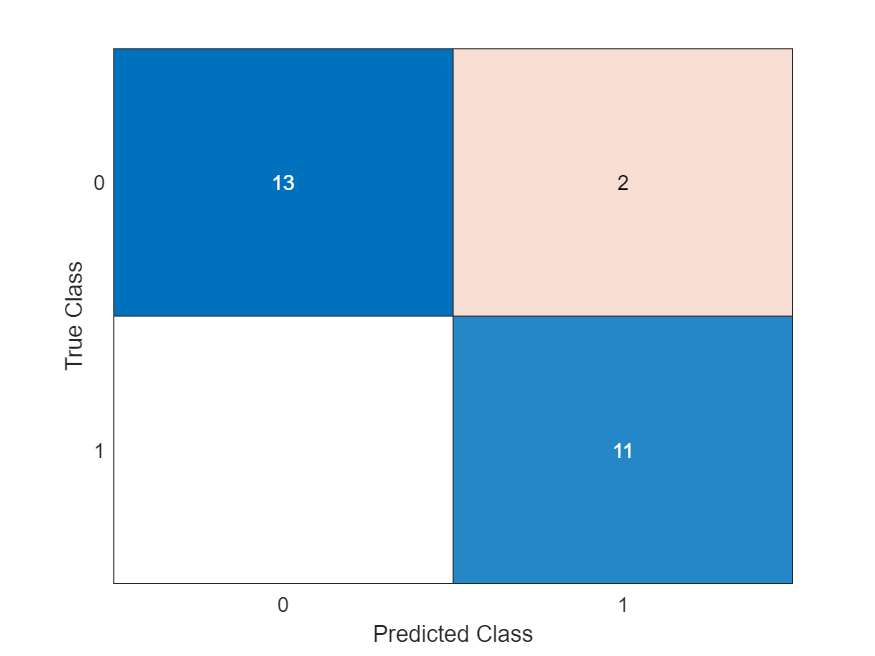

%K-nearest neighbors
vecinos = 7;
distancias = "hamming";
clf = fitcknn(Xtrain,Ytrain,NumNeighbors=vecinos,Distance=distancias);% modelo knn
labelsPredicted  = predict(clf,Xtrain); % se hacen las predicciones apartir del modelo con los datos de entrenamiento
[correctPredictions,~] =size(find((labelsPredicted == Ytrain)==1)); % calcula las predicciones correctas
[AllPredictions,~] = size(labelsPredicted); % da el numero todal de predicciones
accurracy = (correctPredictions/AllPredictions)  * 100; % calcula la precision del modelo
lost = 100 - accurracy; % Da en porcentaje el numero de prediciones erroneas
confusionchart(Ytrain,labelsPredicted) % muestra la matriz de confusion

disp("Precision: " + string(accurracy));

Precision: 92.3077


disp("Perdida: " + string(lost));

Perdida: 7.6923


## Funciones de ayuda

function [x,y] = separateSets(indices,X,Y)
    x = [X(indices(1),:)];
    y = [Y(indices(1),:)];
    [~,tam] = size(indices);
    for index = 2:tam
        x = [x; X(indices(index),:)];
        y = [y; Y(indices(index),:)];
    end
end

function cleaned = preprocesamiento(path,file)
    lines = lower(readlines(strcat(path,"/",file)));
    remove = emptyString(lines,find(lines == ""));
    documentTokenized = tokenizedDocument(remove);
    stopwords = readlines('../data file/stopwords.txt');
    cleaned = removeWords(documentTokenized,stopwords,"IgnoreCase",true);
    cleaned = erasePunctuation(cleaned);
end

function removed = emptyString(lineas,indices)
    [tam,~] = size(lineas);
    removed = [];
    for i= 1:tam
       [rows,~] = size(find(indices == i));
       if rows == 0
            removed = [removed lineas(i)];
       end
    end
    removed = string(removed);
end

